# Using KO paper dataset


$$$\begin{cases}
    \frac{dx_1}{dt}=a\,x_2\,x_3\\
    \frac{dx_2}{dt}=b\,x_1\,x_3\\
\frac{dx_3}{dt}=-(a+b)\,x_1\,x_2
\end{cases} \Longrightarrow
\begin{cases}
    f_1 = \frac{dx_1}{dt} -a\,x_2\,x_3\\
    f_2 = \frac{dx_2}{dt} - b\,x_1\,x_3\\
    f_3 = \frac{dx_3}{dt}+(a+b)\,x_1\,x_2
\end{cases}$$$


### (1) plot u_test vs f_train

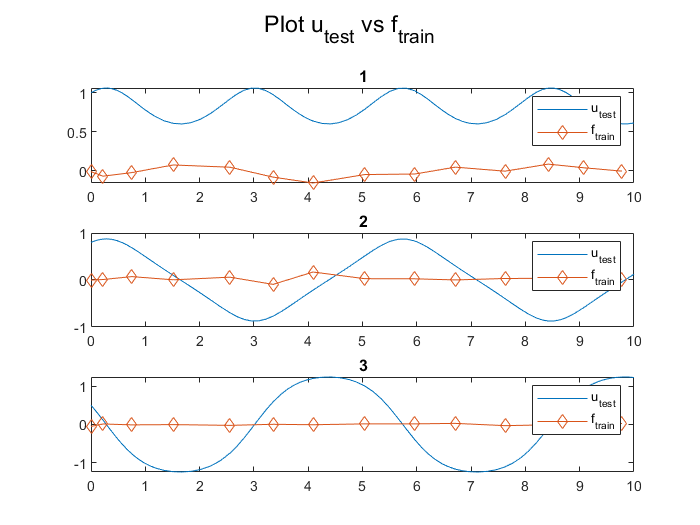

clear;
load('KO_train.mat');
figure
subplot(3,1,1), plot(t_test,u_test(:,1), t_f_train, f_train(:,1),'d-')
legend('u_{test}', 'f_{train}')
title('1')
subplot(3,1,2), plot(t_test,u_test(:,2), t_f_train, f_train(:,2),'d-')
legend('u_{test}', 'f_{train}')
title('2')
subplot(3,1,3), plot(t_test,u_test(:,3), t_f_train, f_train(:,3),'d-')
legend('u_{test}', 'f_{train}')
title('3')
sgtitle('Plot u_{test} vs f_{train}')

### (2) Plot du/dt vs f_train (computing the derivative with centered method)

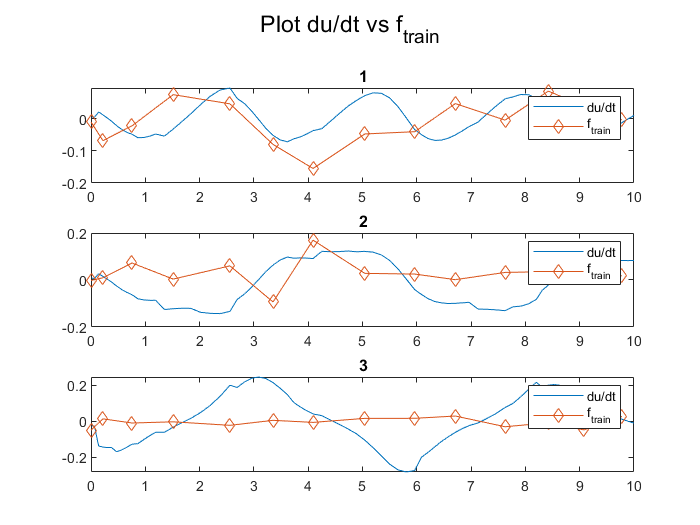

meno_u = [];
meno_t = [];
for i = 1:length(t_test)-1
    meno_t = [meno_t t_test(i+1) - t_test(i)];
    meno_u = [meno_u; u_test(i+1,:) - u_test(i,:)];
end
meno_t = meno_t';
du = (meno_u)./(meno_t);

figure
subplot(3,1,1), plot(t_test(2:end),meno_u(:,1), t_f_train, f_train(:,1),'d-')
title('1')
legend('du/dt', 'f_{train}')
subplot(3,1,2), plot(t_test(2:end),meno_u(:,2), t_f_train, f_train(:,2),'d-')
title('2')
legend('du/dt', 'f_{train}')
subplot(3,1,3), plot(t_test(2:end),meno_u(:,3), t_f_train, f_train(:,3),'d-')
title('3')
legend('du/dt', 'f_{train}')
sgtitle('Plot {du}/{dt} vs f_{train}')

### (3) Plot du/dt vs f_train (computing the derivative with the system)

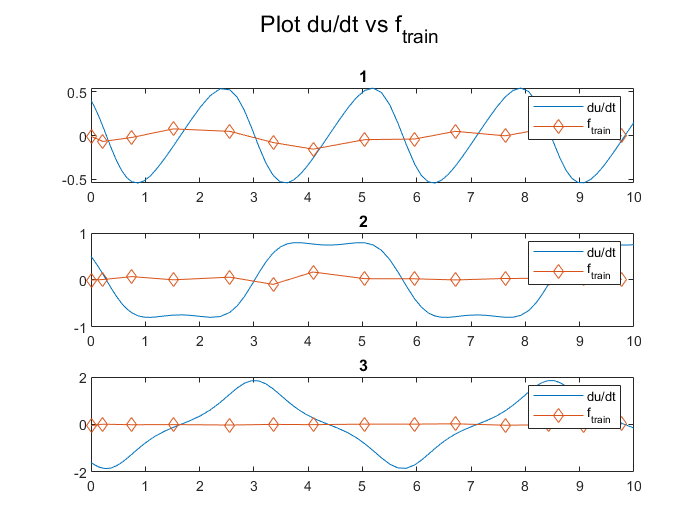

a = 1; b = 1;
f = @(t,x) [a*x(2).*x(3); b*x(1).*x(3); -(a+b)*x(1).*x(2)];

sol = [];
for i = 1:length(t_test)
    sol = [sol, f(t_test(i), u_test(i,:))];
end
sol = sol';

figure
subplot(3,1,1), plot(t_test,sol(:,1), t_f_train, f_train(:,1),'d-')
title('1')
legend('du/dt', 'f_{train}')
subplot(3,1,2), plot(t_test,sol(:,2), t_f_train, f_train(:,2),'d-')
title('2')
legend('du/dt', 'f_{train}')
subplot(3,1,3), plot(t_test,sol(:,3), t_f_train, f_train(:,3),'d-')
title('3')
legend('du/dt', 'f_{train}')
sgtitle('Plot du/dt vs f_{train}')

### (4) Plot f vs f_train

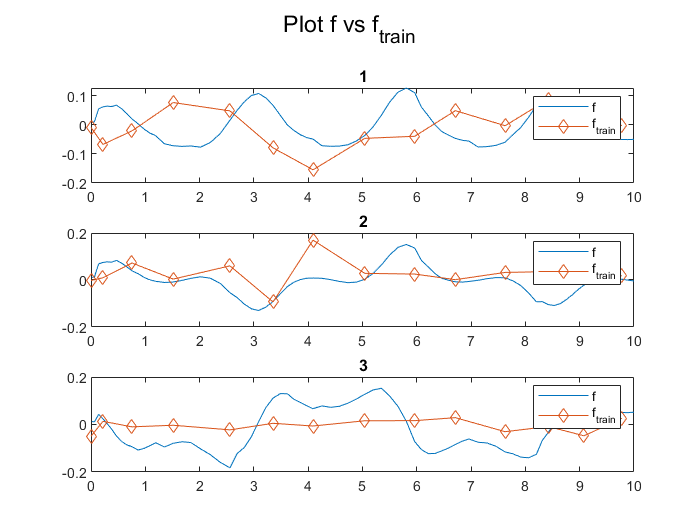

du_sol = du - sol(2:end,:);

figure
subplot(3,1,1), plot(t_test(2:end),du_sol(:,1), t_f_train, f_train(:,1),'d-')
title('1')
legend('f', 'f_{train}')
subplot(3,1,2), plot(t_test(2:end),du_sol(:,2), t_f_train, f_train(:,2),'d-')
title('2')
legend('f', 'f_{train}')
subplot(3,1,3), plot(t_test(2:end),du_sol(:,3), t_f_train, f_train(:,3),'d-')
title('3')
legend('f', 'f_{train}')
sgtitle('Plot f vs f_{train}')

clear;
a = 1; b = 1;
f = @(t,x) [a*x(2).*x(3); b*x(1).*x(3); -(a+b)*x(1).*x(2)];
[t,y] = ode45(f,[0 10],[1.1 1 0.5]);

t_u_test = t;
u_test = y;
t_train = t(2:6:end);
u_train = y(2:6:end,:);

meno_u = [];
meno_t = [];
sol = [];
for i = 1:length(t_train)-1
    meno_t = [meno_t t_train(i+1) - t_train(i)];
    meno_u = [meno_u; u_train(i+1,:) - u_train(i,:)];
    sol = [sol, f(t_train(i+1), u_train(i+1,:))];
end
meno_t = meno_t';
du = (meno_u)./(meno_t);
clear meno_t meno_u;
sol = sol';

t_f_train = t_train(2:end);
f_train = du - sol(:,:);
clear i t y sol;
save('myKO.mat','t_train','t_u_test','u_test','u_train','t_f_train','f_train');